# Assessing model performance

**Author:** Scott Campit

**Contact:** scampit@umich.edu

## Motivation

We have discussed several machine learning models, and how they operate under the hood. In this lesson, we will discuss how to do the following:

- Selecting the best model out of all the different possible models you could have used

- Assessing the performance of a fitted model against a test data set

## Training and test error

Let's consider any model, which we will denote as $f^*$. 

Recall that the goal of any modeling approach is to estimate the real relationship between our inputs/outputs $\left(f\right)$ using the model we're training $\left(f^* \right)$. However, how do we know that the model we are training can be generalized to other datasets? **In other words, how do we know how well our model captures reality? **

The way to we will determine whether our model works well or not is to split the data into two sets: one that the model will use to learn the relationships between the predictors and response (**the training set**), and another dataset that the model has never seen before, and that we'll use to evaluate the model performance (**the test set**). 

### Splitting data into a training and testing set

In practice, for any modeling approach, we need to split our dataset into two sets: a training set ($X_{\mathrm{train}} \;\mathrm{and}\;Y_{\mathrm{train}}$), and a testing set ($X_{\mathrm{test}} \;\mathrm{and}\;Y_{\mathrm{test}}$). 

To do that, we can use the `trainTestSplit` function, which splits up a dataset into these two sets randomly using a fixed percentage value. The documentation and the formulation is shown below.

#### trainTestSplit function

`trainTestSplit` separates the the predictors ( `X` ) and response ( `Y` ) variables into a training and test set. 

**INPUT:**

`X`:                                                 An array consisting of the predictors, where the number of observations span the row space and the predictor variables span the column space.

`Y`:                                                 An array consisting of the targets, where the number of observations span the row space and the targets span the column space.

`trainingSize (optional)`: A floating point value between 0 and 1 denoting the size of the dataset for training. The default value is `0.80` or 80%.

`randomState (optional)`:   A string or integer denoting whether or not the data should be randomly shuffled. The default value is `Default`.

**OUTPUT:**

`Xtrain`:                                      A numeric array consisting of input training set.

`Ytrain`:                                      A numeric array consisting of input test set.

`Xtest`:                                        A numeric or string array consisting of output training set.

`Ytest`:                                        A numeric or string array consisting of input test set.

### Computing the training and validation (test) error using the holdout validation method

Once we have split the training and the test dataset, we can train the model. To illustrate this, I will use the `fisheriris` dataset and train a K-nearest neighbor classifier.

load fisheriris.mat
X = meas

X =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


Y = species

Y = 150×1 cell array
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    {'vers

% Create the training and testing dataset
trainingSize = 0.8; randomstate = 2;
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomstate);

% Fit the k-nearest neighbor classifier
mdl = fitcknn(Xtrain, Ytrain)

mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'setosa'  'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 120
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


## K-fold cross validation

The holdout validation provides some measure of how well a model does perform with a new dataset. However, if we re-fit the model using the same dataset and same splitting procedure, but change the seed value, we will get a different output. In fact, if we repeat this procedure $t$ times, we will get $t$ different accuracies and models. Thus, **the holdout accuracy is not a stable metric we can use to evaluate our model because of its high bias with the training set**.

This is because the model parameters will vary due to the new randomly sampled training dataset. So how do we account for randomness and variation between training dataset? 

We can use the **cross validation** procedure. The step-by-step procedure is outlined below and the validation we will perform is shown in the diagram:

- Split the dataset into a training a test validation set.

- For the training dataset, split the training dataset further into k-parts or **k-folds**. In practice, the dataset is usually split into 5-folds or 10-folds.

- For each $k^{\mathrm{th}}$ fold, we will train on $k-1$folds, while testing and evaluating the accuracy on one of the folds. We need to cache the trained model, and the accuracy associated with that model.

- After we perform all k-folds, **we pick the model with the highest accuracy from k-fold cross validation**. This is the model that best represents the dataset.

- Finally, we will compute the accuracy from the holdout set. **We will use the accuracy from the holdout with the best model as the reported accuracy (ie in a publication)**.

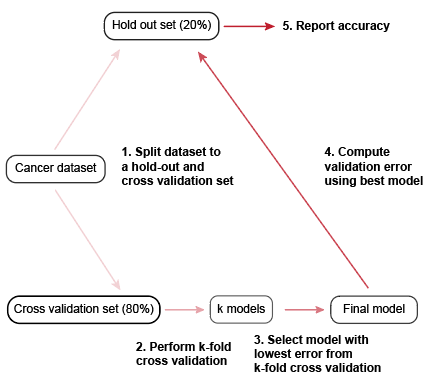

### Implementing k-fold cross validation

Shown below is the `crossValidate` function used to perform k-fold cross validation, including the documentation.

#### `crossValidate` MATALB function

`crossValidate` performs k-fold cross validation and outputs the results from k-fold cross validation as well as a confusion matrix for binary classification.

**INPUTS:**

`Xtrain`:  A numerical matrix of the training input dataset, where the predictors span the columns and each observation span the rows.

`Xtest`: A numerical matrix of the input validation dataset,where the predictors span the columns and each observation span the rows.

`Ytrain:` A vector of the training output dataset, where the targets span the columns and each observation span the rows.

`Ytest: `A vector of the test output dataset, where the targets span the columns and each observation span the rows.

`params (optional)`:  A structure containing hyperparameters, if relevant to the chosen model `type`. If empty, the params will be an empty cell array.

`kfold (optional)`: A scalar value denoting how folds to split the training dataset further. The default value is 10 fold cross validation.

`type`: A string or cell array denoting the type of model (ie a shallow neural network, logitistic regression, etc)

**OUTPUTS:**

`Summary`: A structure consisting of the mean and class accuracies from k-fold cross validation.

function Summary = crossValidate(Xtrain, Ytrain, Xtest, Ytest, ...
                                    params, kfold, type)
   
    % Generate cross validation indices from the Ytrain variable.
    idx = crossvalind('Kfold', size(Ytrain, 1), kfold);
    
    % Train 10 models using 10-fold cross validation
    model    = cell(1:kfold);
    Accuracy = cell(1:kfold);
    for i = 1:kfold
        Xtrain2 = Xtrain(idx ~= i, :);
        Ytrain2 = Ytrain(idx ~= i);
        Xtest2  = Xtrain(idx == i, :);
        Ytest2  = Ytrain(idx == i);
        
        % Switch between model types. Currently, the models available are
        % shallow neural networks (SNN) and logistic regression.
        switch type
            case 'SNN'
                model{i}            = SNN(Xtrain2, Ytrain2, params);
                ypred2              = mdlPredict(model{i}, Xtest2, Ytest2, type);
                decisionBoundary    = mean(ypred2);
                ypred2(ypred2 > decisionBoundary) = 1; ypred2(ypred2 < decisionBoundary) = 0;
              
            case 'Logistic'
                beta = mnrfit(Xtrain2, categorical(Ytrain2));
                model{i}.theta = beta;
                ypred2 = mnrval(model{i}.theta, Xtest2);
                ypred2 = round(ypred2(:, 2)); % Same as using a decision boundary
        end
        
        % Evaluate the ith model and compute the average class accuracy.
        cm            = confusionmat(Ytest2, double(ypred2));
        Accuracy{i}   = sum(diag(cm)) / sum(cm, 'all');
    end
    
    % Obtain the best performing model from k-fold cross validation
    [~, idx] = max([Accuracy{:}]);
    finalModel = model{idx};
    
    % Compute the holdout accuracy from the best performing model.
    switch type
        case 'SNN'
            ypred = mdlPredict(finalModel, Xtest, Ytest, type);
            decisionBoundary    = mean(ypred);
            ypred(ypred > decisionBoundary) = 1; ypred(ypred < decisionBoundary) = 0;
        
        case 'Logistic'
            ypred = mnrval(finalModel.theta, Xtest);
            ypred = round(ypred);
    end
    
    % Get model metrics
    TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
    malignant_precision = (TP) / (TP + FP);
    malignant_recall    = (TP) / (TP + FN);
    benign_precision    = (TN) / (TN + FP);
    benign_recall       = (TN) / (TN + FN);
    average_accuracy    = sum(diag(cm)) / sum(cm, 'all');
    
    % Save everything into a MATLAB structure
    Summary.cm = cm; Summary.NormalizedCM = cm / length(ypred);
    Summary.malignant_precision = malignant_precision; Summary.benign_precision = benign_precision;
    Summary.malignant_recall = malignant_recall; Summary.benign_recall = benign_recall;
    Summary.average_accuracy = average_accuracy; 
end

**The cross validation procedure outlined above has several strengths:**

- We are reducing the bias problem that we encounter in the holdout metric.

- As it turns out, the variance between k-fold cross validation procedures is low, making this a really good estimate of the model accuracy. 

- This method is also not as computationally intensive as the next method described below.

## Leave-one-out-cross-validation (LOOCV)

While cross validation is a powerful method to choose the best model and evaluate model accuracy, it can still be somewhat biased, depending on random chance and how the dataset was split into k-folds (which really, may be due to bad luck). 

One method that does address this issue is the **leave-one-out-cross-validation (LOOCV)** procedure. The idea behind LOOCV is to train the model on all observations except 1, and compute the test error on the left out observation.

This method is the most stable validation method we can use to evaluate our model, as we are essentially overfitting the model and seeing the contribution each observation in the model has on model accuracy. It is also pretty computationally intensive. 

## Summary

In practice, we use k-fold cross validation to choose the best model and assess model accuracy, while using leave-one-out-cross-validation to assess how each observation in the model contributes to overall model performance.